clc; clear; close all;

% Load CSV
data = readmatrix('project_3');

mic1 = data(:,1);
mic2 = data(:,2);
mic3 = data(:,3);
mic4 = data(:,4);


Fs = 16000;              % Sampling frequency (Hz)
Ts = 1/Fs;               % Sampling period
N = length(mic1)      % Number of samples

N = 5547

N = 4500;
t0 = N-200

t0 = 4300

tf = N

tf = 4500

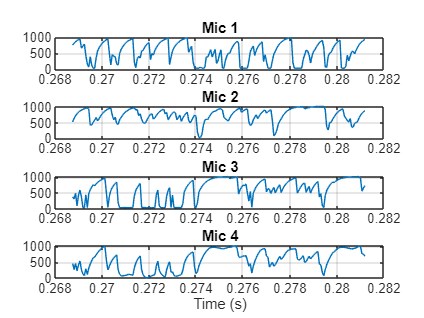

t = (t0:N-1)*Ts;          % Time vector


mic1 = mic1(t0+1:N);
mic2 = mic2(t0+1:N);
mic3 = mic3(t0+1:N);
mic4 = mic4(t0+1:N);
figure;

subplot(4,1,1);
plot(t, mic1);
title('Mic 1'); grid on;

subplot(4,1,2);
plot(t, mic2);
title('Mic 2'); grid on;

subplot(4,1,3);
plot(t, mic3);
title('Mic 3'); grid on;

subplot(4,1,4);
plot(t, mic4);
title('Mic 4'); grid on;

xlabel('Time (s)');

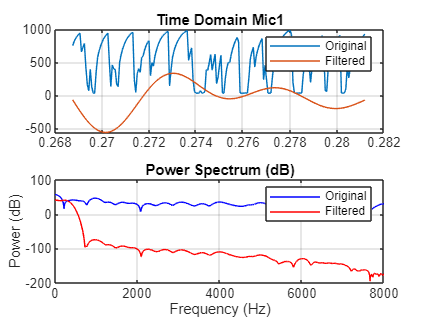

% Lowpass
mic1_f = bandpass(mic1, [85 250], Fs);
mic2_f = bandpass(mic2, [85 250], Fs);
mic3_f = bandpass(mic3, [85 250], Fs);
mic4_f = bandpass(mic4, [85 250], Fs);

% Mic 1
figure;
subplot(2,1,1);
plot(t, mic1); hold on;
plot(t, mic1_f);
title('Time Domain Mic1');
legend('Original','Filtered');
grid on;

subplot(2,1,2);

[po1,fo1] = pspectrum(mic1, Fs);
[pf1,ff1] = pspectrum(mic1_f, Fs);

plot(fo1, 10*log10(po1), 'b'); hold on;
plot(ff1, 10*log10(pf1), 'r');

title('Power Spectrum (dB)');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
legend('Original','Filtered');
grid on;

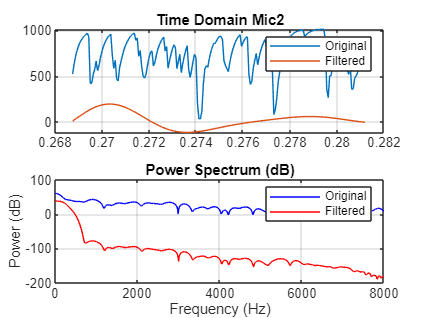


% Mic 2
figure;
subplot(2,1,1);
plot(t, mic2); hold on;
plot(t, mic2_f);
title('Time Domain Mic2');
legend('Original','Filtered');
grid on;

subplot(2,1,2);

[po2,fo2] = pspectrum(mic2, Fs);
[pf2,ff2] = pspectrum(mic2_f, Fs);

plot(fo2, 10*log10(po2), 'b'); hold on;
plot(ff2, 10*log10(pf2), 'r');

title('Power Spectrum (dB)');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
legend('Original','Filtered');
grid on;

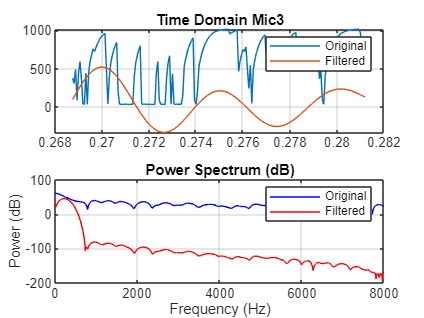


% Mic 3
figure;
subplot(2,1,1);
plot(t, mic3); hold on;
plot(t, mic3_f);
title('Time Domain Mic3');
legend('Original','Filtered');
grid on;

subplot(2,1,2);

[po3,fo3] = pspectrum(mic3, Fs);
[pf3,ff3] = pspectrum(mic3_f, Fs);

plot(fo3, 10*log10(po3), 'b'); hold on;
plot(ff3, 10*log10(pf3), 'r');

title('Power Spectrum (dB)');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
legend('Original','Filtered');
grid on;

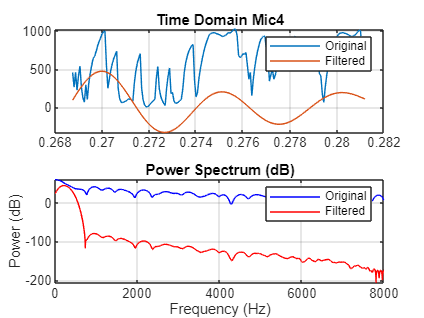


% Mic 4
figure;
subplot(2,1,1);
plot(t, mic4); hold on;
plot(t, mic4_f);
title('Time Domain Mic4');
legend('Original','Filtered');
grid on;

subplot(2,1,2);

[po4,fo4] = pspectrum(mic4, Fs);
[pf4,ff4] = pspectrum(mic4_f, Fs);

plot(fo4, 10*log10(po4), 'b'); hold on;
plot(ff4, 10*log10(pf4), 'r');

title('Power Spectrum (dB)');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
legend('Original','Filtered');
grid on;

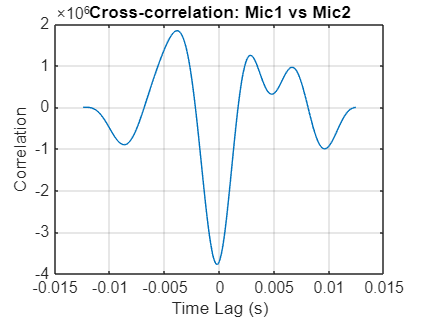

% Cross-correlation

% Mic 1&2
[xc12, lags12] = xcorr(mic1_f, mic2_f);

[~, idx12] = max(abs(xc12));
lag12 = lags12(idx12);
delay12 = lag12 / Fs;

figure;
plot(lags12/Fs, xc12);
xlabel('Time Lag (s)');
ylabel('Correlation');
title('Cross-correlation: Mic1 vs Mic2');
grid on;

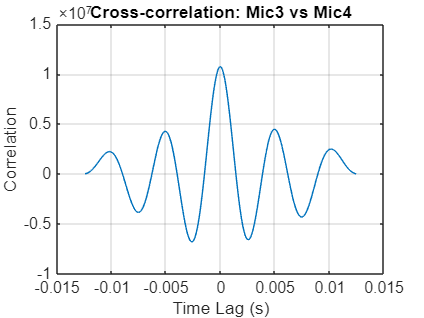


% Mic 3&4
[xc34, lags34] = xcorr(mic3_f, mic4_f);

[~, idx34] = max(abs(xc34));
lag34 = lags34(idx34);
delay34 = lag34 / Fs;

figure;
plot(lags34/Fs, xc34);
xlabel('Time Lag (s)');
ylabel('Correlation');
title('Cross-correlation: Mic3 vs Mic4');
grid on;


fprintf('Delay Mic1-Mic2: %.6f s\n', delay12);

Delay Mic1-Mic2: -0.000250 s


fprintf('Delay Mic3-Mic4: %.6f s\n', delay34);

Delay Mic3-Mic4: 0.000000 s


L = 0.1;
c = 343;

%delay12
val = c * delay12 / L;
val = max(min(val, 1), -1);   % clamp to [-1,1]

disp("stand on the left")

stand on the left


%delay34
val2 = c * delay34 / L;
val2 = max(min(val2, 1), -1);   % clamp to [-1,1]

phi12 = rad2deg(acos(val))

phi12 = 149.0370

phi34 = rad2deg(acos(val2))

phi34 = 90